# **RS-HL-15-3: State Value Change**

**Hongseok Kim**

**UT Austin Oden Institute**

**07/20/24**

### **I. Load the Dataset**

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('~/RS_Dataset/RS_HL_3_dataset.mat')

### II. Destination Setting and Time Index Vector Setting

time_index_vector = 1:200;


number_of_agents = 48;
number_of_destinations = 1;
state_vector = 1:48;


% start_state = state_vector(randi(numel(state_vector), 1, number_of_agents));
% destination_values = randsample(state_vector,number_of_destinations);
% destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
% start_time = start_time_index(randi(numel(start_time_index), 1, number_of_agents));

% destination_value = randsample(state_vector,number_of_destinations);
destination_value = 40;

#### II.1 Run the MDP simulation for each destination

fprintf('Total Number of Destinations: %d\n', number_of_destinations);

Total Number of Destinations: 1


fprintf('--------------------------------------\n')

--------------------------------------


fprintf('Running MDP , Destination %d \n',destination_value);

Running MDP , Destination 40 


MDP.(['MDP', num2str(destination_value)]) = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_value);

simulation set up complete! 
Value Iteration: 100
Value Iteration: 200
Value Iteration: 300
Value Iteration: 400
Value Iteration: 500
Value Iteration: 600
Value Iteration: 700
Value Iteration: 800
Value Iteration: 900
Value Iteration: 1000
Policy: 1 -> Value Iteration: 1080
Policy: 2 -> Value Iteration: 23
Policy: 3 -> Value Iteration: 13
Policy: 4 -> Value Iteration: 10
Policy: 5 -> Value Iteration: 6
Policy: 6 -> Value Iteration: 2


fprintf('--------------------------------------\n')

--------------------------------------


#### **II.2 Capture the state value change given MDP structure**

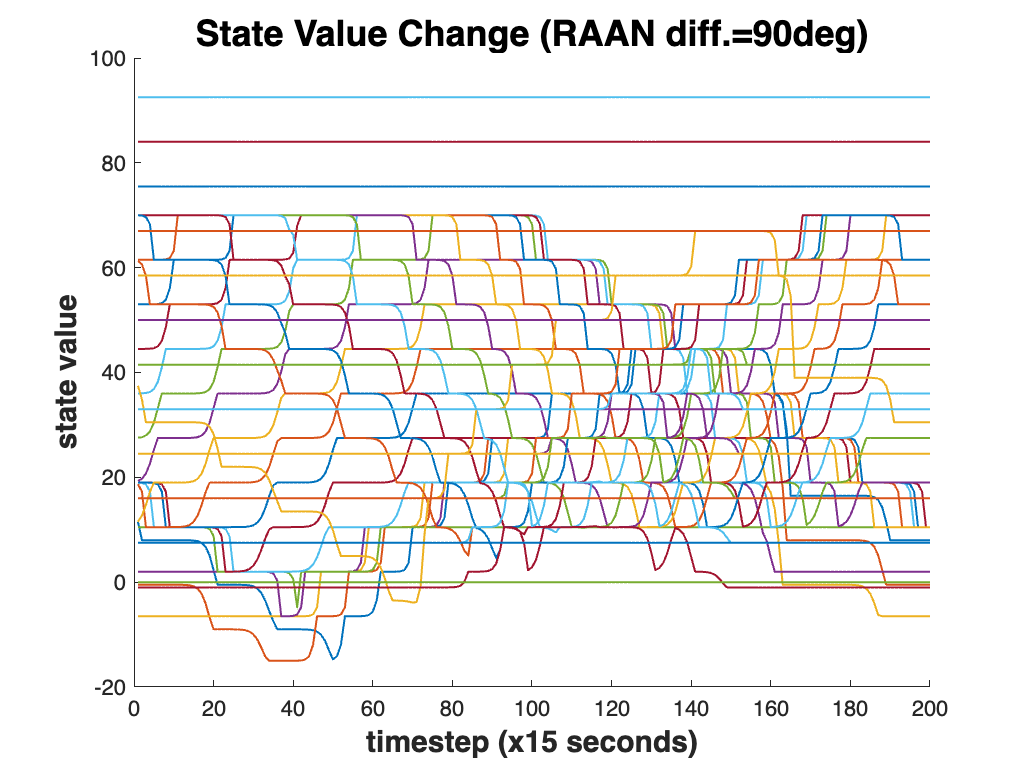

state_change_value_matrix = zeros(length(time_index_vector),length(state_vector));
    
for time_index = time_index_vector
    for state_index = state_vector
        state_value_number = MDP.(['MDP', num2str(destination_value)]).(['time' num2str(time_index)]).(['state' num2str(state_index)]).('state_value');
        state_change_value_matrix(time_index-min(time_index_vector)+1,state_index) = state_value_number;
    end
end
figure;
hold on
for state_index = state_vector
   plot(time_index_vector,state_change_value_matrix(:,state_index),'LineWidth',1)
end
hold off
title('State Value Change (RAAN diff.=90deg)','FontSize',18,'FontWeight','bold')
xlabel('timestep (x15 seconds)','FontSize',15,'FontWeight','bold')
ylabel('state value','FontSize',15,'FontWeight','bold')